## 1. Linear regression with one variable

### 1.1 Plotting the data

housePriceObject = housePriceObject();  %Create a new housePrice object

housePriceObject.data = load('ex1data1.txt'); %csvread('sample_submission.csv');   % skips the first row of data
housePriceObject.X = housePriceObject.data(:, 1); housePriceObject.y = housePriceObject.data(:, 2);

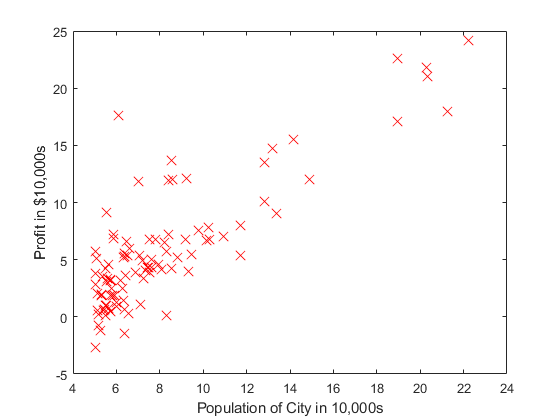

plotData(housePriceObject.X, housePriceObject.y);

### 1.2 Gradient Descent

housePriceObject.m = length(housePriceObject.X) % number of training examples

housePriceObject =   housePriceObject with properties:

          data: [97×2 double]
             X: [97×1 double]
             y: [97×1 double]
         theta: [3×1 double]
         alpha: 0.1000
     num_iters: 400
             m: 97
    iterations: 1500
            mu: [2.0007e+03 3.1702]
         sigma: [794.7024 0.7610]


housePriceObject.X = [ones(housePriceObject.m, 1), housePriceObject.data(:,1)]; % Add a column of ones to x
housePriceObject.theta = zeros(2, 1); % initialize fitting parameters
housePriceObject.iterations = 1500;
housePriceObject.alpha = 0.01;

#### 1.2.1 Computing the cost $\mathit{\mathbf{J}}\left(\theta \right)$

% Compute and display initial cost with theta all zeros
computeCost(housePriceObject.X, housePriceObject.y, housePriceObject.theta, housePriceObject.m)

ans = 32.0727

% Compute and display initial cost with non-zero theta
computeCost(housePriceObject.X, housePriceObject.y,[-1; 2], housePriceObject.m)

ans = 54.2425

#### 1.2.2 Gradient descent

% Run gradient descent:
% Compute theta
housePriceObject.theta = gradientDescent(housePriceObject.X, housePriceObject.y, housePriceObject.theta, housePriceObject.alpha, housePriceObject.iterations, housePriceObject.m);

% Print theta to screen
% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f,\n%f',housePriceObject.theta(1),housePriceObject.theta(2))

Theta computed from gradient descent:
-3.630291,
1.166362

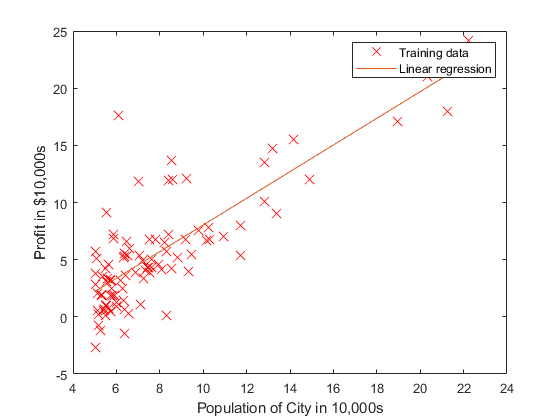

% Plot the linear fit
hold on; % keep previous plot visible
plot(housePriceObject.X(:,2), housePriceObject.X* housePriceObject.theta, '-')
legend('Training data', 'Linear regression')
hold off % don't overlay any more plots on this figure

% Predict values for population sizes of 35,000 and 70,000
predict1 = [1, 3.5] * housePriceObject.theta;
fprintf('For population = 35,000, we predict a profit of %f\n', predict1*10000);

For population = 35,000, we predict a profit of 4519.767868


predict2 = [1, 7] * housePriceObject.theta;
fprintf('For population = 70,000, we predict a profit of %f\n', predict2*10000);

For population = 70,000, we predict a profit of 45342.450129


# 3D Grh.

% Visualizing J(theta_0, theta_1):
% Grid over which we will calculate J
theta0_vals = linspace(-10, 10, 100);
theta1_vals = linspace(-1, 4, 100);

% initialize J_vals to a matrix of 0's
J_vals = zeros(length(theta0_vals), length(theta1_vals));

% Fill out J_vals
for i = 1:length(theta0_vals)
    for j = 1:length(theta1_vals)
	  t = [theta0_vals(i); theta1_vals(j)];    
	  J_vals(i,j) = computeCost(housePriceObject.X, housePriceObject.y, t, housePriceObject.m);
    end
end

# Surface plot

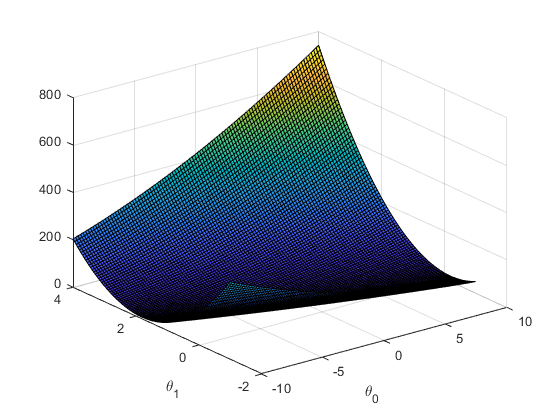

% Because of the way meshgrids work in the surf command, we need to 
% transpose J_vals before calling surf, or else the axes will be flipped
J_vals = J_vals';

% Surface plot
figure;
surf(theta0_vals, theta1_vals, J_vals)
xlabel('\theta_0'); ylabel('\theta_1');

# Contour plot

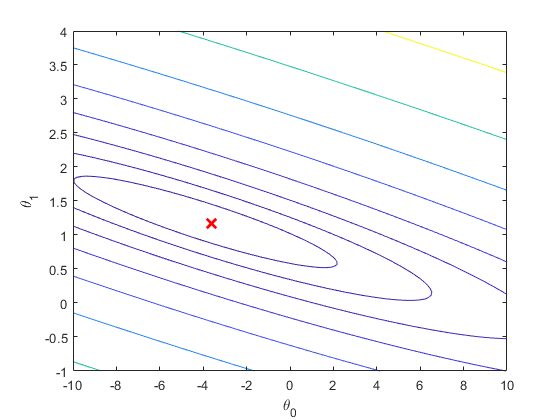

% Contour plot
figure;
% Plot J_vals as 15 contours spaced logarithmically between 0.01 and 100
contour(theta0_vals, theta1_vals, J_vals, logspace(-2, 3, 20))
xlabel('\theta_0'); ylabel('\theta_1');
hold on;
plot(housePriceObject.theta(1), housePriceObject.theta(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
hold off;

## 2. Linear regression with multiple variables

% Load Data
housePriceObject.data = load('ex1data2.txt'); %csvread('sample_submissionMulti.csv');%
housePriceObject.X = housePriceObject.data(:, 1:2);
housePriceObject.y = housePriceObject.data(:, 3);
housePriceObject.m = length(housePriceObject.y);

% Print out some data points
% First 10 examples from the dataset
fprintf(' x = [%.0f %.0f], y = %.0f \n', [housePriceObject.X(1:10,:) housePriceObject.y(1:10,:)]');

 x = [2104 3], y = 399900 
 x = [1600 3], y = 329900 
 x = [2400 3], y = 369000 
 x = [1416 2], y = 232000 
 x = [3000 4], y = 539900 
 x = [1985 4], y = 299900 
 x = [1534 3], y = 314900 
 x = [1427 3], y = 198999 
 x = [1380 3], y = 212000 
 x = [1494 3], y = 242500 


### 2.1 Feature Normalization

% Scale features and set them to zero mean
[housePriceObject.X, housePriceObject.mu, housePriceObject.sigma] = featureNormalize(housePriceObject.X);

% Add intercept term to X
housePriceObject.X = [ones(housePriceObject.m, 1) housePriceObject.X];

### 2.2 Gradient Descent

% Run gradient descent
% Choose some alpha value
housePriceObject.alpha = 0.1;
housePriceObject.num_iters = 400;

% Init Theta and Run Gradient Descent 
housePriceObject.theta = zeros(3, 1);
[housePriceObject.theta, ~] = gradientDescentMulti(housePriceObject.X, housePriceObject.y, housePriceObject.theta, housePriceObject.alpha, housePriceObject.num_iters, housePriceObject.m);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f,\n%f',housePriceObject.theta(1),housePriceObject.theta(2))

Theta computed from gradient descent:
340412.659574,
110631.048958

### 2.3 Normal Equations

% Solve with normal equations:
% Load Data
housePriceObject.data = load('ex1data2.txt');%csvread('sample_submissionMulti.csv');
housePriceObject.X = housePriceObject.data(:, 1:2);
housePriceObject.y = housePriceObject.data(:, 3);
housePriceObject.m = length(housePriceObject.y);

% Add intercept term to X
housePriceObject.X = [ones(housePriceObject.m, 1) housePriceObject.X];

% Calculate the parameters from the normal equation
housePriceObject.theta = normalEqn(housePriceObject.X, housePriceObject.y);

% Display normal equation's result
fprintf('Theta computed from the normal equations:\n%f\n%f', housePriceObject.theta(1),housePriceObject.theta(2));

Theta computed from the normal equations:
89597.909544
139.210674